clc;clear;

配置系统参数

P = 1;
Nt = 8;
Nrf = 4;
T = 20;
fc = 24e9;
c = 3e8;
lamda = c/fc;
spacing = lamda/2;
TxAntLoc = spacing*(0:Nt-1);

参数初始化，t=1

Frf = zeros(Nt,Nrf,T);
Sbb = zeros(Nrf,T);
Sdp = zeros(Nt,T);
Rs = zeros(Nt,Nt,T);
Rs_norm = zeros(Nt,Nt,T);

Frf(:,:,1) = ones(Nt,1)*ones(Nrf,1).';
Sbb(:,1) = sqrt(P/(Nrf^2*Nt))*ones(Nrf,1);
Sdp(:,1) = Frf(:,:,1)*Sbb(:,1);
Rs(:,:,1) = Sdp(:,1)*Sdp(:,1)';
Rs_norm(:,:,1) = normalize(Rs(:,:,1),'norm');

波形变换

u = exp(1i*2*pi/T.*(1:Nt));
vt = exp(1i*pi/T.*(2.*(1:T)-1));
for nt = 2:T
    Frf(:,:,nt) = diag(u)*Frf(:,:,nt-1);
    Sbb(:,nt) = Sbb(:,nt-1).*vt(nt);
    Sdp(:,nt) = Frf(:,:,nt)*Sbb(:,nt);
    Rs(:,:,nt) = 1/T*Sdp(:,nt)*Sdp(:,nt)';
    Rs_norm(:,:,nt) = normalize(Rs(:,:,nt),'norm');
end

绘制方向图

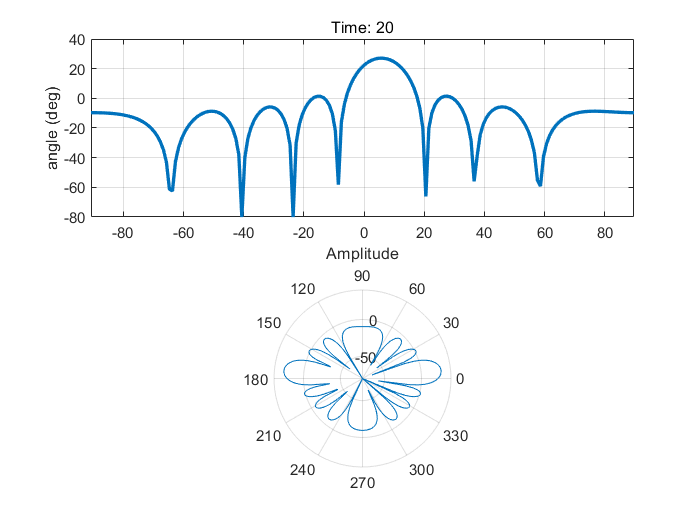

angleSpace = linspace(-pi, pi, 360);
angleSpaceDeg = linspace(-180, 180, 360);
a = zeros(Nt, length(angleSpace));
for j = 1:Nt
    a(j,:) = exp((1i * 2 * pi * TxAntLoc(j) / lamda) .* sin(angleSpace));
end
d = zeros(360,T);
for nt = 1:T
    for i = 1:length(angleSpace)
        d(i,nt) = transpose(a(:,i)) * Rs_norm(:,:,nt) * conj(a(:,i));
    end
end
tiledlayout(2,1) 
nexttile 
p(1) = plot(angleSpaceDeg(90:270), mag2db(abs(d(90:270,1))), 'LineWidth', 2);
grid on;axis tight
ht = title("Time: 1");
xlabel("Amplitude")
ylabel("angle (deg)")
ylim([-80 40]);
nexttile 
d1 = d;
d1(mag2db(abs(d1))<-80) = 10^(-80/20);
p(2) = polarplot(angleSpace, mag2db(abs(d1(:,1))));
rlim([-80 40])
for nt = 1:T
    set(p(1),XData=angleSpaceDeg(90:270),YData=mag2db(abs(d1(90:270,nt))));
    set(p(2),XData=angleSpace,YData=mag2db(abs(d1(:,nt))));
    set(ht,String="Time: "+nt)
    pause(0.5);
    drawnow
    F=getframe(gcf);
    I=frame2im(F);
    [I,map]=rgb2ind(I,256);
%     pathname = mfilename('fullpath');
%     [pathname,~] = fileparts(pathname);
%     pathname = strip(pathname);
pathname = 'D:\OneDrive\Graduate\Code\MIMO-OFDM-Wireless-Communications-with-MATLAB\';
    if nt == 1
        imwrite(I,map,[pathname,'PilotSignal.gif'],'gif','Loopcount',inf,'DelayTime',0.2);
        
    else
        imwrite(I,map,[pathname,'PilotSignal.gif'],'gif','WriteMode','append','DelayTime',0.2);
        
    end
end